# **TP1 CMSI : RESOLUTION DE SYSTEME**

On va tester et comparer l'efficacite de trois differentes methodes de resolution de systeme AX = B

*rayon spectral :* plus grand module de ses valeurs propres

pour que Jacobi et Gauss convergent : A doit etre inversible et à diagonale strictement dominante

dans le cas de non-convergence : limiter le nombre d'iterations

dans le cas de convergence : limiter le nombre d'iterations avec la qualite de la solution obtenue => evaluer l'erreur en multipliant la solution X par A et en faisant la difference avec B (AX-B <= precision)

on va deja clear tout ce qu'il y avait avant pour liberer un peu la memoire

clc
clear

*input :* matrices A, vecteur B, precision

*output : *le vecteur solution, le nombre d'iterations

%A = [-6 2 -1 5 ; 1 3 0 -2 ; 2 1 -7 2 ; 5 1 2 -6];
%A = [8 2 -4 1 ; 3 6 1 -2 ; -1 1 5 0 ; 1 1 4 3];
%A = [10 0 11 ; 1 6 0 ; 10 0 11];
%A = [15 1 -1 4 6 2 5; 1 5 2 0 1 2 1 ; 2 -1 -6 1 1 0 2 ; 1 0 2 10 2 2 1 ; 0 2 3 4 16 2 1 ; 1 2 1 3 2 19 0 ; 12 3 2 5 3 6 32];
%B = [2 ; 17 ; -18 ; 3 ; 1 ; 6 ; 2];
A = randi([-10,15],4,4)

A =     -8    14     0    10
    -4     1    10     0
     0    -2    -5     3
    10     7    -5    -5


B = randi([-10,15],4,1)

B =     10
     3
    -9
    11


precision = 1e-6;

on test ca avec les trois fonctions

%   il est necessaire d'avoir A inversible et à diagonale strictement
%   dominante
diagDominant(A);

Matrix A is not diagonally dominant!


square(A);
[resJacobi, i] = Jacobi(A, B, precision)

resJacobi = 1.0e+307 *

       Inf
   -8.5554
   -1.1557
       Inf


i = 593

%   il est necessaire d'avoir A inversible et à diagonale strictement
%   dominante
diagDominant(A);

Matrix A is not diagonally dominant!


square(A);
[resGauss, i] = Gauss(A, B, precision)

resGauss =   -Inf
   NaN
   NaN
   NaN


i = 234

[resRelax, i, w] = Relaxation(A, B, precision)

resRelax = 1.0e+307 *

   -0.4192
   -1.9961
    0.6764
      -Inf


i = 232

w = 0

tableau pour stocker les temps d'execution des trois methodes

i = 1;
comp = zeros(500,4);

on test avec les trois fonctions, et avec un pas de 0.0005

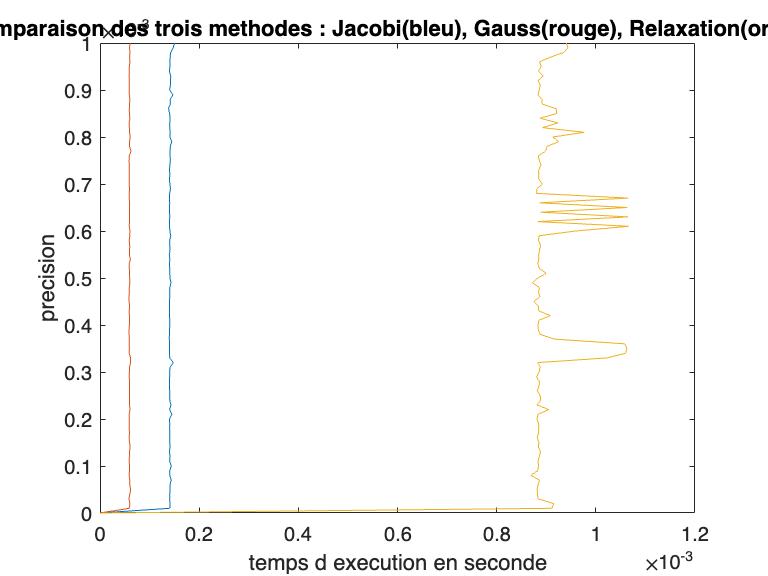

for precision = 1e-3 : -0.00001 : 1e-6
    comp(i, 1) = precision;
    jac = @() Jacobi(A, B, precision);
    comp(i, 2) = timeit(jac);
    gauss = @() Gauss(A, B, precision);
    comp(i, 3) = timeit(gauss);
    relax = @() Relaxation(A, B, precision);
    comp(i, 4) = timeit(relax);
    i = i+1;
end

% on plot les resultats: les temps et la precision
figure(1);
plot(comp(:, 2), comp(:, 1), ...
    comp(:, 3), comp(:, 1), ...
    comp(:, 4), comp(:, 1))
title('comparaison des trois methodes : Jacobi(bleu), Gauss(rouge), Relaxation(orange)')
% legendes des axes
xlabel('temps d execution en seconde')
ylabel('precision')

on obtient un tableau et un graphique en 2D avec:

1e colonne: precision sur l'axe des ordonnées

2e colonne: temps d'execution de jacobi en bleu

3e colonne: temps d'execution de gauss en rouge

4e colonne: temps d'execution de relaxation en orange

#### **Avantages (et un peu inconveinents) de chaque méthode**

**Jacobi: **temps execution relativement constant, contrairement à Relaxation, mais avec un grand nombre d'iterations. Elle a un seul avantage par rapport aux autres, c'est qu'elle est parallélisable (en gros, elle peut être fractionnée en plusieurs étapes élémentaires afin d'exécuter ces parties simultanément et donc diminuer le temps de calcul).

**Gauss:** methode la plus rapide en terme de temps d'execution, converge plus rapidement (relaxation jusque 100 fois plus de temps d'execution), beaucoup moins d'iterations si valeurs importantes dans les coins haut droit et bas gauche. C'est parce que on utilise à l'étape i les résultats des étapes précédentes (1 : i-1), donc les valeurs qui viennent juste d'être updated.

**Relaxation: **permet d'obtenir trois versions de Gauss grace à omega, celle que l'on vient de voir, la sous-relaxée et la sur-relaxée; le nombre d'iterations decroit avec oméga

    *0 < omega < 1 :* sous relaxation --> X moyenne ponderale entre valeur actuelle et valeur precedente // aide à faire converger un système qui ne converge pas

    *omega = 1 :* gauss, X inchangé

    *1 < omega < 2 :* sur relaxation // aide à accélerer la convergence d'un système qui est déjà convergent

En gros, permet de réduire le nombre d'iterations si on a quelque chose qui converge.

Pour des valeurs importantes dans les coins haut droit et bas gauche, le nombre d'iterations (et donc le temps d'execution) augmente considerablement (et la methode de jacobi n'est pas du tout optimal pour ca)

**En general, l'avantage des methodes iteratives par rapport aux methodes directes :**

c'est qu'il n'est pas nécessaire de connaitre la matrice A, seulement pouvoir calculer les produits A$\vec x$, et on économise au niveau du stockage parce qu'on n'a pas à stocker les factorisations d'une méthode directe.

Cependant, les méthodes itératives ont besoin d'une condition d'arrêt pour être efficaces.

(exemple méthode directe : factorisation QR avec Q matrice orthogonale - $QQ^T = I$ - et R upper triang matrix)